## **The PhysIO toolbox - Overview**

The fundamental question in functional magentic resonance imaging (fmri) is to identify the BOLD (blood oxygen level dependent) effect **signal in the brain** that correlates with a task at hand (for example, hearing a sound), indicating brain activity related to that task.

However, **noise** from physiological origins weakens the BOLD signal.

Modelling the noise together with the signal can incerse the specificity of the signal and the **SNR** (signal to noise ratio).

## **Types of physiological noise on the bold signal**

**The hemodynamic response function (hdf) in fMRI**

Experiements in the 1990 showed that the brain's response to a stimulus, for example a tone, is an increse in blood oxygenation in the brainregion that is active while processing that stimulus. It could further be shown that this blood level increse could be modelled by the hemodynamic respnse function, which can be approximated by two gamma functions:


$$\textrm{BOLD}=\textrm{hdf}\left(x,\textrm{shape},\textrm{scale}\right)$$


You can change the shape of the hdf by entering shape  and scale parameters below.

x = 0:0.01:10;
hdf = spm_Gpdf(x, 3, 8);

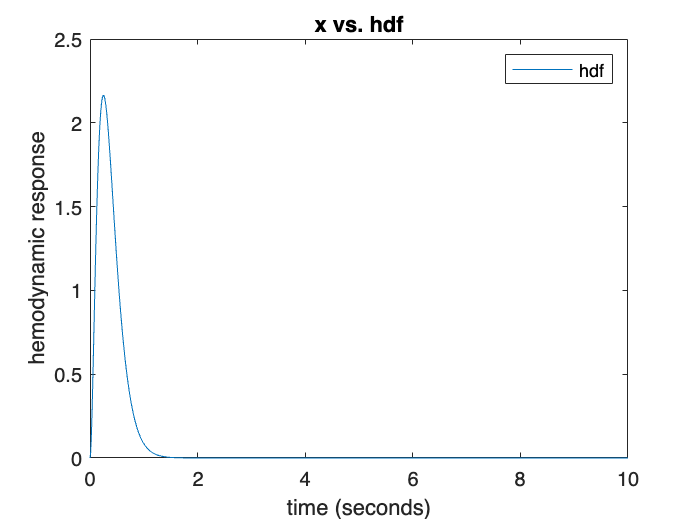

% Create plot of x and hdf
h = plot(x,hdf,"DisplayName","hdf");

% Add xlabel, ylabel, title, and legend
xlabel("x")
ylabel("hdf")
title("x vs. hdf")
legend

xlabel("time (seconds)")
ylabel("hemodynamic response")

 Let us model two stimuli (e.g two tones that are perceived by the auditory cortex):

s = repmat(0, 1, 1001);
s(300:350) =1;
s(500:550)= 1;

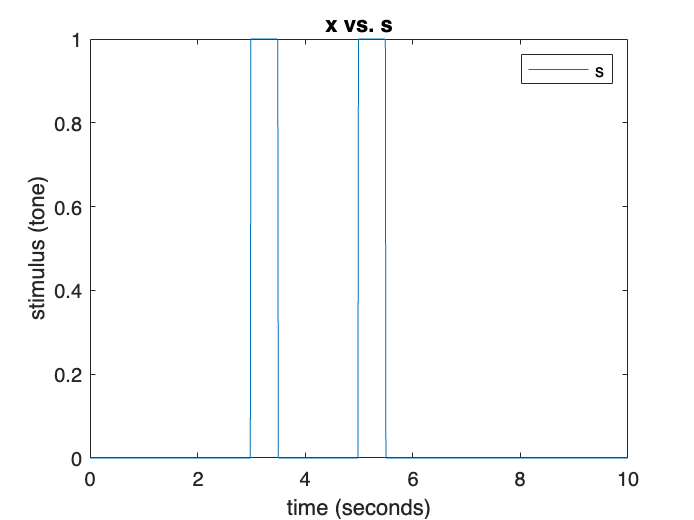

% Create plot of x and s
h2 = plot(x,s,"DisplayName","s");

% Add xlabel, ylabel, title, and legend
xlabel("x")
ylabel("s")
title("x vs. s")
legend

xlabel("time (seconds)")
ylabel("stimulus (tone)")

Due to the effect of convolution we can predict the brain's response to two auditory stmuli and model the hemodynamic response:

x2 = 0:0.01:20;
response = conv(s, hdf);

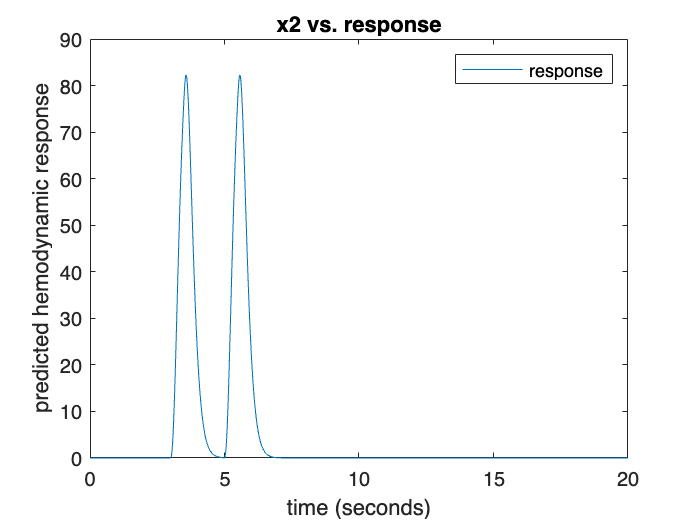

% Create plot of x2 and response
h3 = plot(x2,response,"DisplayName","response");

% Add xlabel, ylabel, title, and legend
xlabel("x2")
ylabel("response")
title("x2 vs. response")
legend

xlabel("time (seconds)")
ylabel("predicted hemodynamic response")

**Types of physiological noise and how to record them**